# Práctica N°4 Control Biológico.

Autor: Tomás Vidal

### Notas

- Hay que aclarar que se empleó un punto de referencia arbitrario para los diferentes controladores. Además se emplean mediciones de $\mu \left(s\right)$, para lo cual se necesitaria un observador

## Preguntas

- ¿Considero $S_{\textrm{in}} \;$como un parámetro con incertidumbre?

- ¿Qué tipo de cultivo tengo? Consideré una alimentación continua Fin=Fout entonces $\dot{V} =0$

- ¿En el modelo de $\mu \left(s\right)$ considero n es staturación y se cancela?

- En el control linealizante, ¿por qué no se llega a la convergencia?

- El método es simplemente ignorar que existe una función dependiente del sustrato? se podría implementar un observador, pero vale la pena? En este caso el sustrato converge a cero de todas maneras

## Proceso de bioplástico (PHB)


$$\[k_{S1} S + k_N N \rightarrow{r_x} X + k_{P1} P\]

\[k_{S2} S \rightarrow{r_p} P\]$$


El proceso es modelado con las siguientes ecuaciones:


$$\[ \dot{x} = r_x x - Dx \]

\[ \dot{s} = -k_{s1} r_x - k_{s2} r_p + D(s_i - s_j) \]

\[ \dot{N} = -k_N r_x + D(n_i - n) \]

\[ \dot{p} = k_{s2} r_p - Dp \]$$


En forma vectorial:


$$
\left[
\begin{array}{c}
\dot{x} \\
\dot{s} \\
\dot{n} \\
\dot{p}
\end{array}
\right]
=
\left[
\begin{array}{c}
1 & 0 \\ 
-K_{s1} & -K_{s2} \\
-K_{N} & 0 \\
K_{p1}  & 1
\end{array}
\right]
*
\left[
\begin{array}{c}
x \\ s \\ n \\ p
\end{array}
\right]
+ D * \left[
\begin{array}{c}
-x \\ s_{in}-s \\ n_{in}-n \\ -p
\end{array}
\right]$$


Pero si se considera que solo vamos a simular la fase de producción de microorganismos, podemos descartar la variación en el plástico, porque no hay producción del mismo y además podemos tomar que la cantidad de nitrógeno es tanta que siempre está en saturación, por lo que no varía tampoco. Entonces se tiene el siguiente modelo reducido:


$$
\left[
\begin{array}{c}
\dot{x} \\
\dot{s} \\
\end{array}
\right]
=
\left[
\begin{array}{c}
1 \\ 
-K_{s1}
\end{array}
\right]
*
\left[
\begin{array}{c}
x \\ s
\end{array}
\right]
- D * \left[
\begin{array}{c}
x \\ s
\end{array}
\right]$$


Además la matrix K se reduce  a 1 columna porque no hay tasa de producción de plástico, por lo explicado anteriormente.

Este modelo reducido de 2x2 es el que se emplea a continuación para todas las simulaciones.

DatosModeloTP4

sim_hours = 50; % la cantidad de horas que se van a simular
timeStep = 1e-2;

% Configuración de la simulación de Simulink
simConfig.StopTime = num2str(sim_hours);
simConfig.Solver = 'ode1';
simConfig.FixedStep = num2str(timeStep);

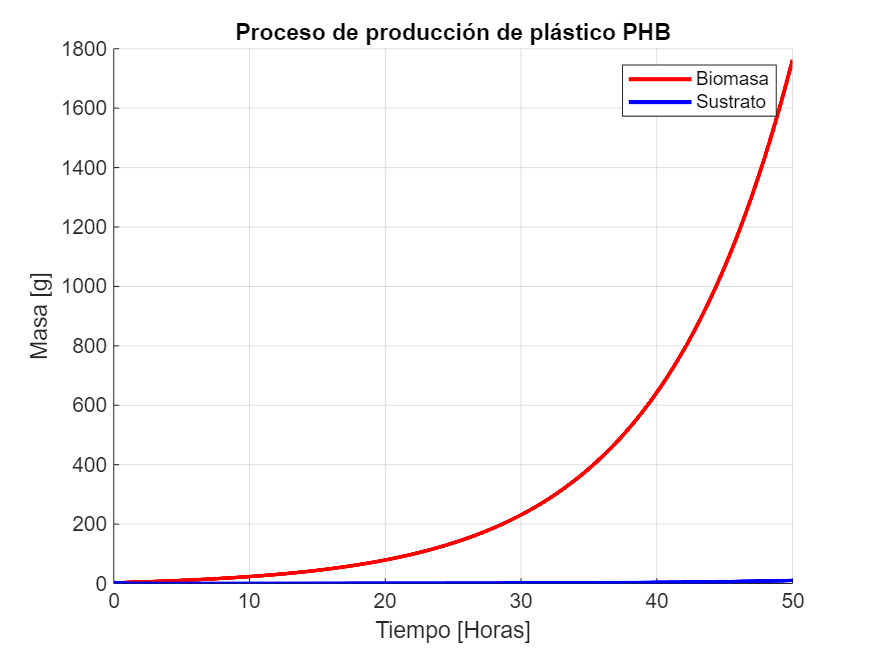

D=0.1;
params={1};
for i=1:length(params)

    sim_out = sim('simulaciones/TP4_sin_control', simConfig);
    
    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrate = reshape(states(:,2), size(time));
    mu = sim_out.mu_s.Data;
    
end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Proceso de producción de plástico PHB');
xlabel('Tiempo [Horas]');
ylabel('Masa [g]');
plot(time, biomass.*volume, 'r', 'LineWidth', 2);
plot(time, sustrate.*volume, 'b', 'LineWidth', 2);
legend('Biomasa', 'Sustrato');

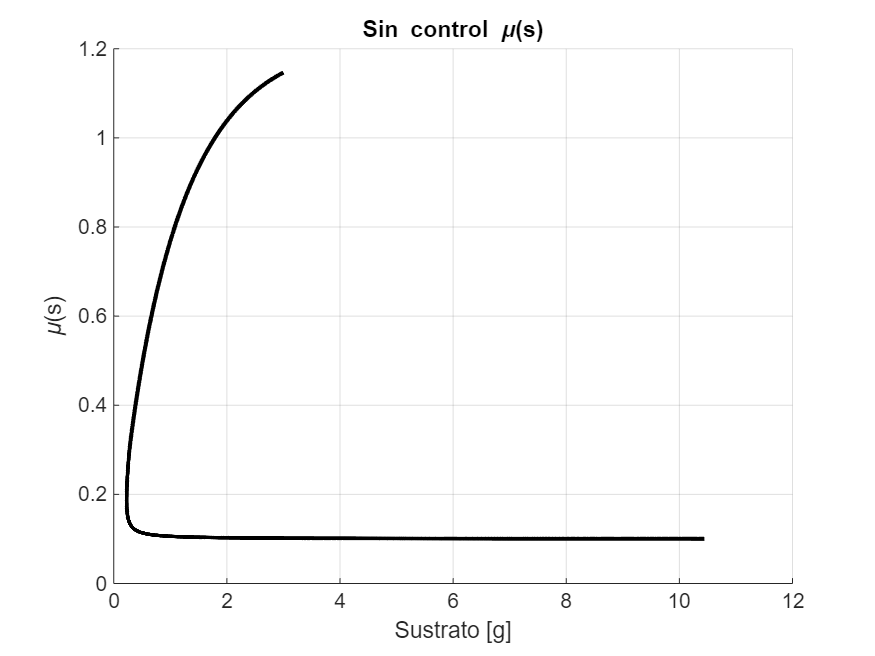


fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Sin control \mu(s)');
xlabel('Sustrato [g]');
ylabel('\mu(s)');
plot(sustrate.*volume, mu, 'k', 'LineWidth', 2);

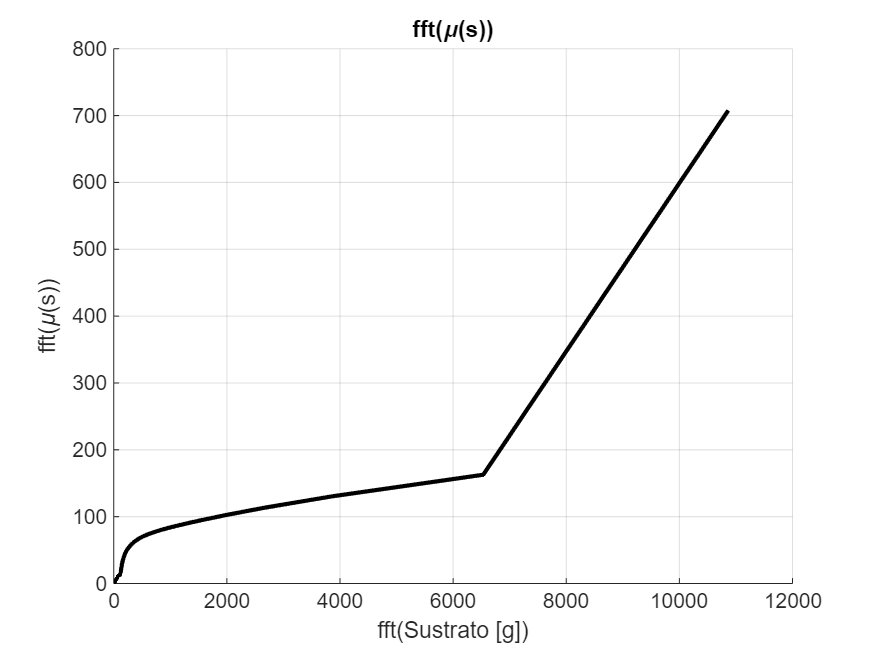


[mu_freq1] = abs(fft(mu));
[s_freq1] = abs(fft(sustrate.*volume));

% Comportamiento en frecuencia de mu
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('fft(\mu(s))');
xlabel('fft(Sustrato [g])');
ylabel('fft(\mu(s))');
plot(s_freq1, mu_freq1, 'k', 'LineWidth', 2);

## Control exponencial a lazo abierto

Se hace una alimentación exponencial de masa a lazo abierto. Se prueban diferentes puntos de operación.

s_r=0.27; % s de referencia a operar
mu_r=0.0845; % mu de referencia a operar

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = 0.126;
modelParameters.mu_r=mu_r;

params={[s_r, mu_r], [4, 0.1], [5, 0.1], [10, 0.15]};
mus=cell(length(params));
sustrates=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)

    modelParameters.s_r = params{i}(1);
    modelParameters.mu_r=params{i}(2);

    % fprintf('Sr=%.3f,mur=%.3f\n', params{i}(1),params{i}(2));

    sim_out = sim('simulaciones/TP4_control_LA', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrates{i} = reshape(states(:,2), size(time)).*volume;
    Do = sim_out.Do.Data;
    mus{i} = sim_out.mu_s.Data;

    mu_r_vector = ones(1, length(mus{i}))*mu_r;
 
    error{i}=(mu_r_vector-mus{i});
    MSE{i} = immse(reshape(mu_r_vector, size(mus{i})), mus{i});
end

Resultados

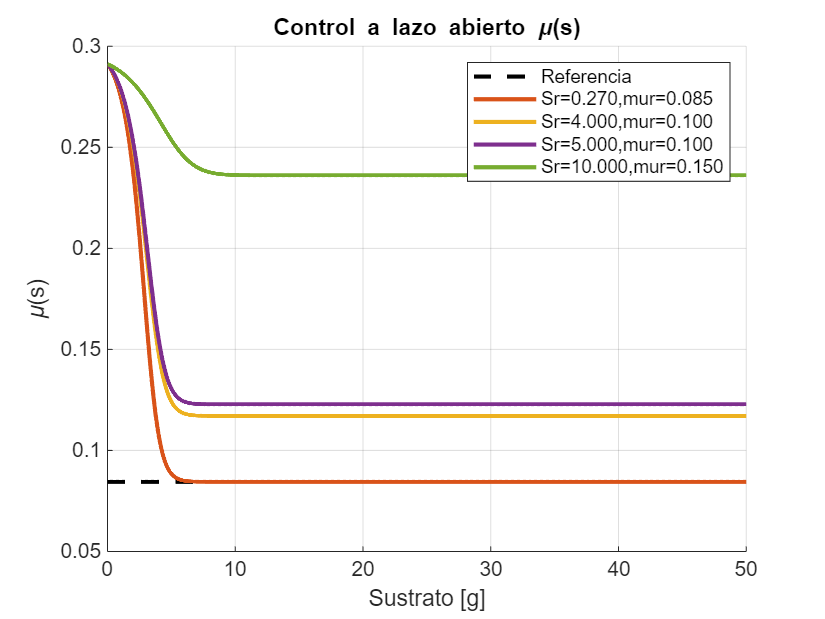

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Control a lazo abierto \mu(s)');
xlabel('Sustrato [g]');
ylabel('\mu(s)');
plot(time, mu_r_vector, 'k--', 'LineWidth', 2);
plot(time, mus{1}, 'LineWidth', 2);
plot(time, mus{2}, 'LineWidth', 2);
plot(time, mus{3}, 'LineWidth', 2);
plot(time, mus{4}, 'LineWidth', 2);

legend('Referencia', sprintf('Sr=%.3f,mur=%.3f', params{1}(1),params{1}(2)), ...
    sprintf('Sr=%.3f,mur=%.3f', params{2}(1),params{2}(2)), ...
    sprintf('Sr=%.3f,mur=%.3f', params{3}(1),params{3}(2)), ...
    sprintf('Sr=%.3f,mur=%.3f', params{4}(1),params{4}(2)));

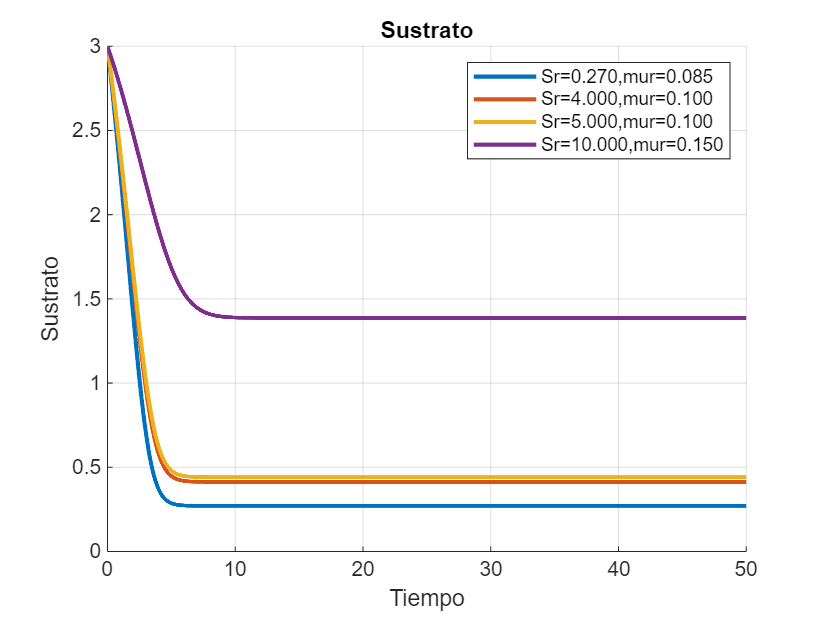


fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Sustrato');
xlabel('Tiempo');
ylabel('Sustrato');
% plot(time, mu_r_vector, 'k--', 'LineWidth', 2);
plot(time, sustrates{1}, 'LineWidth', 2);
plot(time, sustrates{2}, 'LineWidth', 2);
plot(time, sustrates{3}, 'LineWidth', 2);
plot(time, sustrates{4}, 'LineWidth', 2);

legend(sprintf('Sr=%.3f,mur=%.3f', params{1}(1),params{1}(2)), ...
    sprintf('Sr=%.3f,mur=%.3f', params{2}(1),params{2}(2)), ...
    sprintf('Sr=%.3f,mur=%.3f', params{3}(1),params{3}(2)), ...
    sprintf('Sr=%.3f,mur=%.3f', params{4}(1),params{4}(2)));

Errores relativos

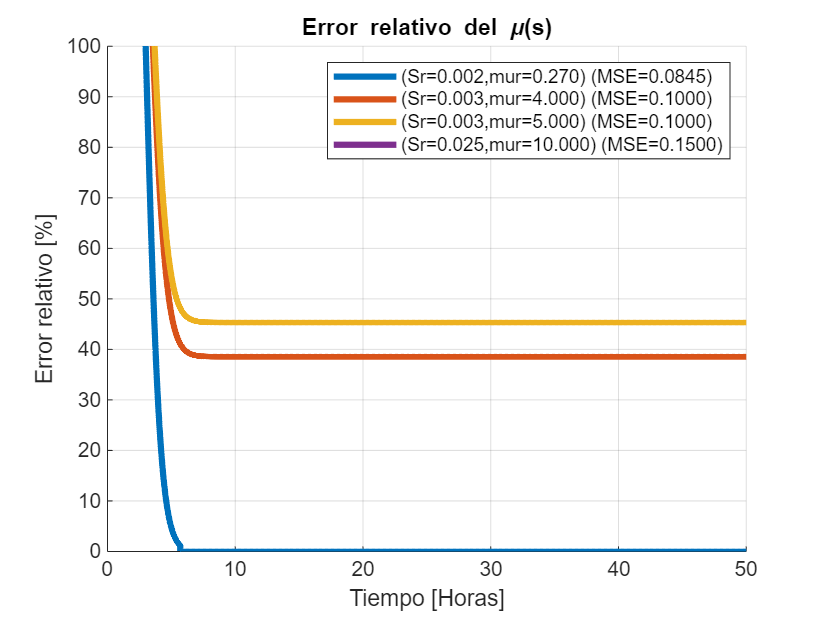

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo del \mu(s)');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{2}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{3}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{4}), mu_r_vector), 'LineWidth', 3);

legend(sprintf('(Sr=%.3f,mur=%.3f) (MSE=%.4f)', MSE{1}, params{1}(1), params{1}(2)), ...
    sprintf('(Sr=%.3f,mur=%.3f) (MSE=%.4f)', MSE{2}, params{2}(1), params{2}(2)), ...
    sprintf('(Sr=%.3f,mur=%.3f) (MSE=%.4f)', MSE{3}, params{3}(1), params{3}(2)), ...
    sprintf('(Sr=%.3f,mur=%.3f) (MSE=%.4f)', MSE{4}, params{4}(1), params{4}(2)));

#### Conclusiones:

Se tiene mucho error y no hay convergencia al punto de referencia deseado

## Variaciones en los parámetros

### Incertidumbre en x0

Controlado con C(s)=Kp y variaciones en las condiciones iniciales:

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = 0.1259;
modelParameters.mu_r=mu_r;

params={x0*(1.2),x0*(0.8)}; % más/menos 20% del x0
mus=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)

    modelParameters.x0=params{i};

    sim_out = sim('simulaciones/TP4_control_LA', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrates = reshape(states(:,2), size(time)).*volume;
    Do = sim_out.Do.Data;
    mus{i} = sim_out.mu_s.Data;

    mu_r_vector = ones(1, length(mus{i}))*mu_r;
 
    error{i}=(mu_r_vector-mus{i});
    MSE{i} = immse(reshape(mu_r_vector, size(mus{i})), mus{i});
end

Ahora se muestran los resultados, comparando el caso cuando se tiene variaciones en las condiciones iniciales y como los controadores empleados responden a estas variaciones, es decir su robustez.

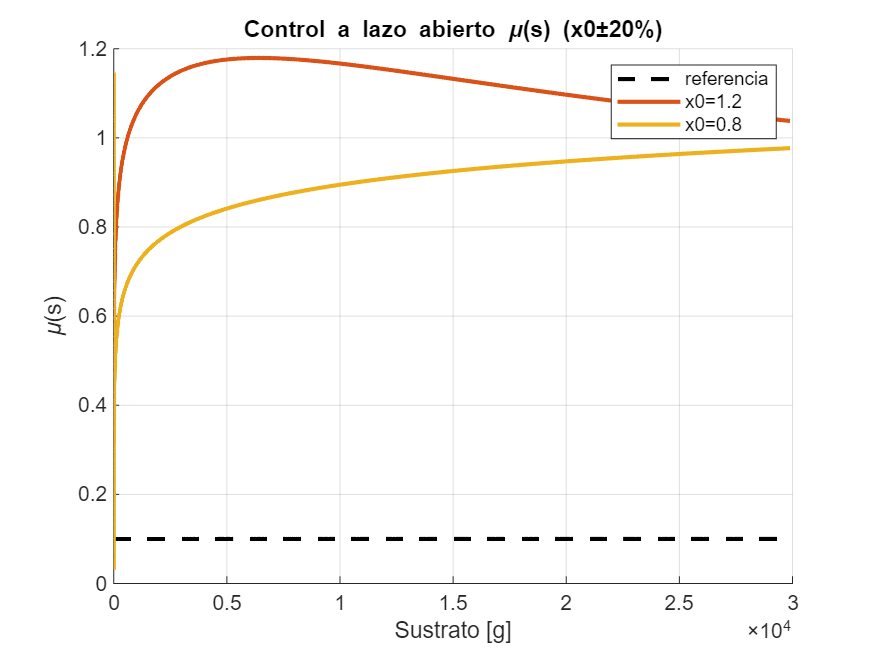

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Control a lazo abierto \mu(s) (x0±20%)');
xlabel('Sustrato [g]');
ylabel('\mu(s)');
plot(sustrates, mu_r_vector, 'k--', 'LineWidth', 2);
plot(sustrates, mus{1}, 'LineWidth', 2);
plot(sustrates, mus{2}, 'LineWidth', 2);

legend('referencia' ...
    ,sprintf('x0=%.1f', params{1}), ...
    sprintf('x0=%.1f', params{2}));

Errores relativos

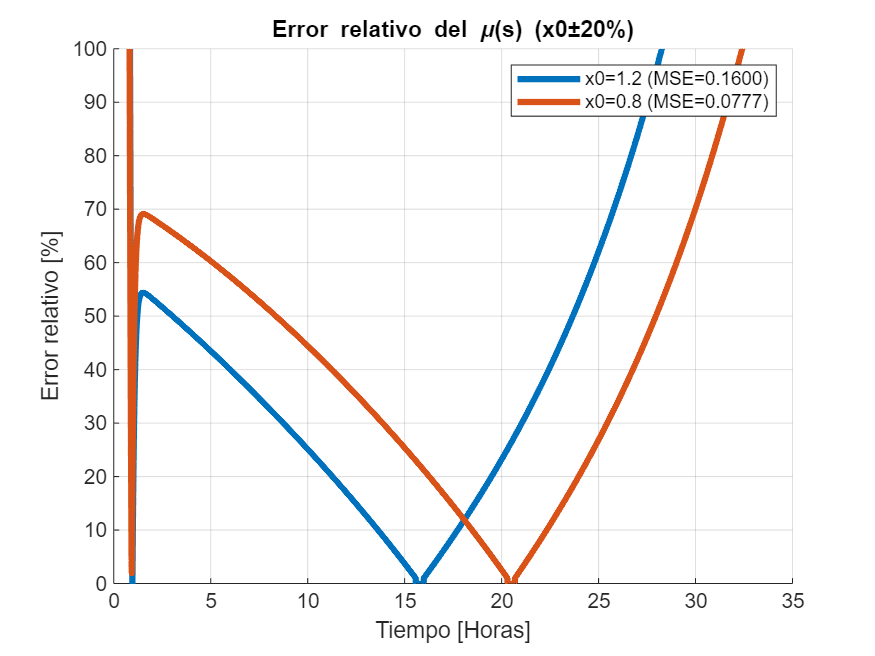

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo del \mu(s) (x0±20%)');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{2}), mu_r_vector), 'LineWidth', 3);

legend(sprintf('x0=%.1f (MSE=%.4f)', params{1}, MSE{1}), ...
    sprintf('x0=%.1f (MSE=%.4f)', params{2}, MSE{2}));

Ambos terminan convergiendo a pesar de tener un error en el valor inicial.

### Incertidumbre en ks1 

Ahora hago lo mismo que antes pero variando $k_{\textrm{s1}}$

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = 0.1259;
modelParameters.mu_r=mu_r;

params_ks={ks1*(1.2),ks1*(0.8)}; % más/menos 20% del ks1
mus_ks=cell(length(params_ks));
error_ks=cell(length(params_ks));
MSE_ks=cell(length(params_ks));
for i=1:length(params_ks)
    modelParameters.K = [1;-params_ks{i}];

    sim_out = sim('simulaciones/TP4_control_LA', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrate_ks = reshape(states(:,2), size(time)).*volume;
    Do = sim_out.Do.Data;
    mus_ks{i} = sim_out.mu_s.Data;

    mu_r_vector = ones(1, length(mus_ks{i}))*mu_r;
 
    error_ks{i}=(mu_r_vector-mus_ks{i});
    MSE_ks{i} = immse(reshape(mu_r_vector, size(mus_ks{i})), mus_ks{i});
end

Ahora se muestran las gráficas

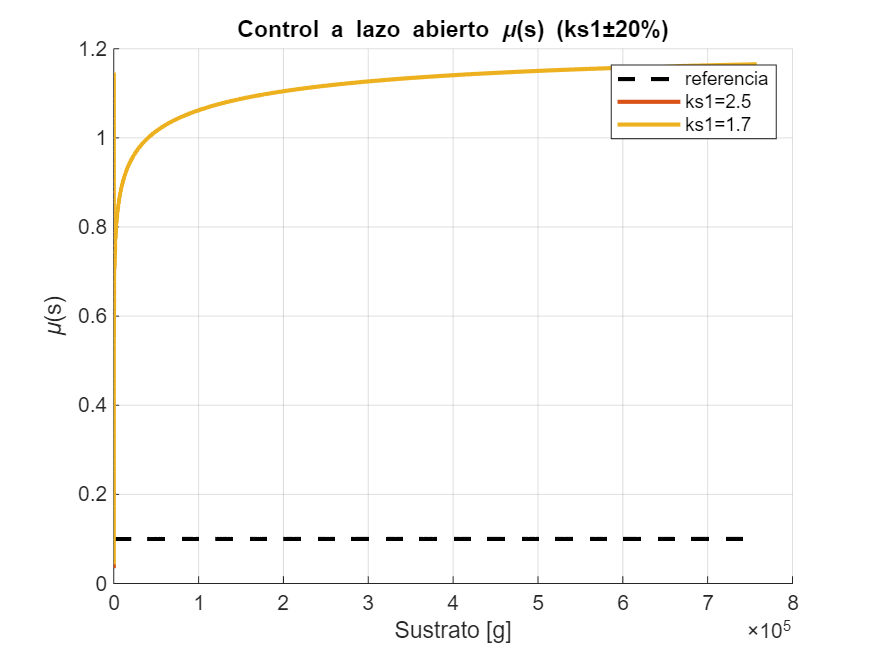

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Control a lazo abierto \mu(s) (ks1±20%)');
xlabel('Sustrato [g]');
ylabel('\mu(s)');
plot(sustrate_ks, mu_r_vector, 'k--', 'LineWidth', 2);
plot(sustrate_ks, mus_ks{1}, 'LineWidth', 2);
plot(sustrate_ks, mus_ks{2}, 'LineWidth', 2);

legend('referencia' ...
    ,sprintf('ks1=%.1f', params_ks{1}), ...
    sprintf('ks1=%.1f', params_ks{2}));

Y las del error relativo son:

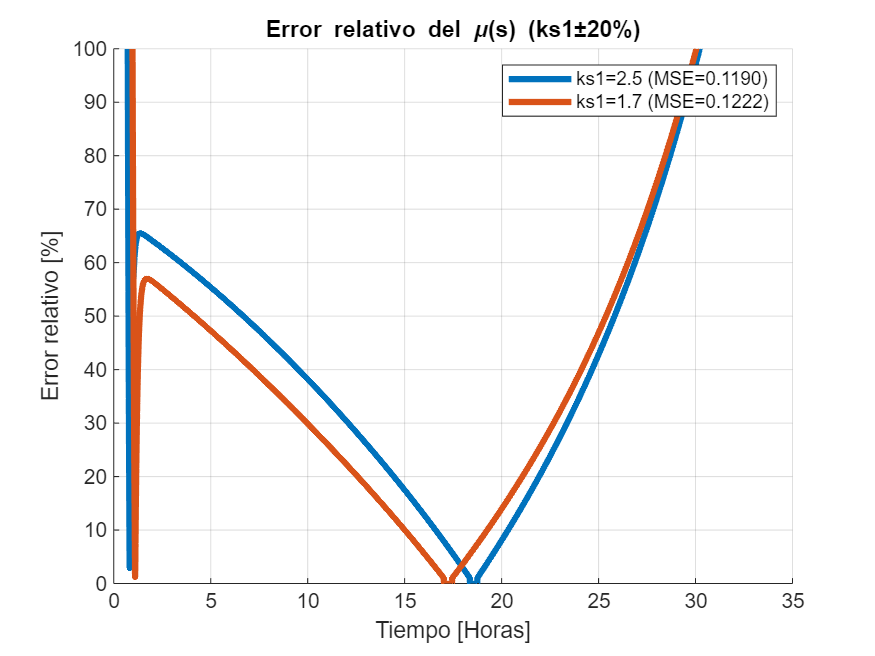

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo del \mu(s) (ks1±20%)');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error_ks{1}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error_ks{2}), mu_r_vector), 'LineWidth', 3);

legend(sprintf('ks1=%.1f (MSE=%.4f)', params_ks{1}, MSE_ks{1}), ...
    sprintf('ks1=%.1f (MSE=%.4f)', params_ks{2}, MSE_ks{2}));

Viendo los resultados, se podría concluir que es más robusto ante variaciones en $k_{\textrm{s1}}$que de $x_0$

## Control a lazo cerrado

### Control proporcional al error

Ahora trato de implementar una ley de alimentación exponencial a lazo cerrado

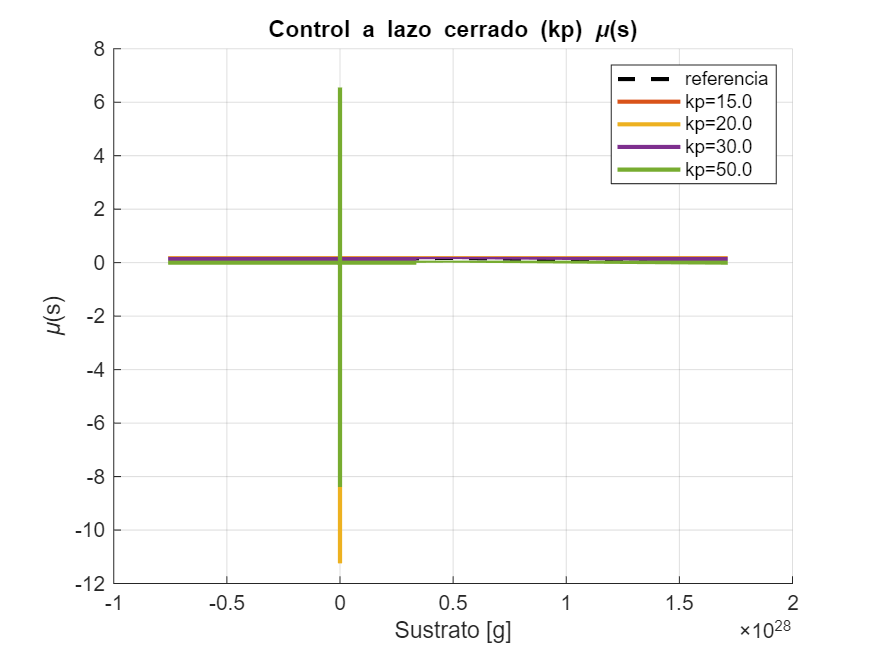

sim_hours2 = 90;
timeStep2 = 0.8*1e-2;
simConfig.StopTime = num2str(sim_hours2);
simConfig.FixedStep = num2str(timeStep2);

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = 0.1259;
modelParameters.mu_r=mu_r;
% modelParameters.kp=0.1; % factor proporcional

params={15, 20, 30, 50};
mus=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)
    modelParameters.kp=params{i};

    sim_out = sim('simulaciones/TP4_control_kp', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrate = reshape(states(:,2), size(time)).*volume;
    Do = sim_out.Do.Data;
    mus{i} = sim_out.mu_s.Data;

    mu_r_vector = ones(1, length(mus{i}))*mu_r;
    
    error{i}=(mu_r_vector-mus{i});
    MSE{i} = immse(reshape(mu_r_vector, size(mus{i})), mus{i});

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Control a lazo cerrado (kp) \mu(s)');
xlabel('Sustrato [g]');
ylabel('\mu(s)');
plot(sustrate, mu_r_vector, 'k--', 'LineWidth', 2);
plot(sustrate, mus{1}, 'LineWidth', 2);
plot(sustrate, mus{2}, 'LineWidth', 2);
plot(sustrate, mus{3}, 'LineWidth', 2);
plot(sustrate, mus{4}, 'LineWidth', 2);

legend('referencia' ...
    ,sprintf('kp=%.1f', params{1}), ...
    sprintf('kp=%.1f', params{2}), ...
    sprintf('kp=%.1f', params{3}), ...
    sprintf('kp=%.1f', params{4}));

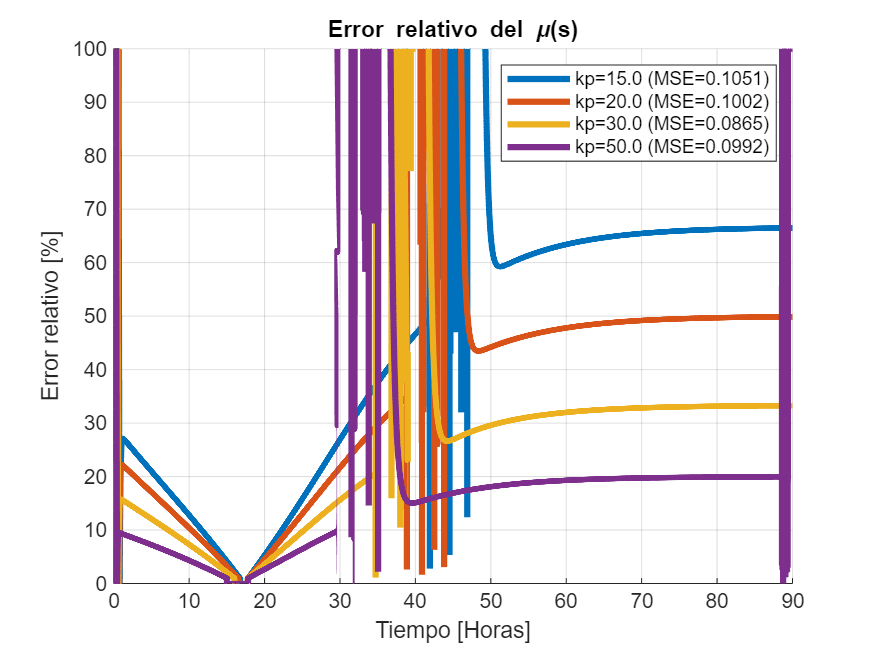


% Error relativo
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo del \mu(s)');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{2}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{3}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{4}), mu_r_vector), 'LineWidth', 3);

legend(sprintf('kp=%.1f (MSE=%.4f)', params{1}, MSE{1}), ...
    sprintf('kp=%.1f (MSE=%.4f)', params{2}, MSE{2}), ...
    sprintf('kp=%.1f (MSE=%.4f)', params{3}, MSE{3}), ...
    sprintf('kp=%.1f (MSE=%.4f)', params{4}, MSE{4}));

#### Conclusiones

Ahora teniendo esta ganancia proporcional al error se tiene mucho menor error final, a diferencia de antes, además y más importante, se tiene una dinámica que termina convergiendo al valor de referencia, aunque el error de convergencia no es 0, sino que se tiene un error al estado estacionario no nulo que depende de la ganancia $k_p$, a medida que esta se incrementa se tiene menor error de estado estacionario, además se puede observar que converge a este valor final aproximadamente en las 70hs, lo cual puede ser o no suficiente.

La simulación no se ve muy bien probablemente por el paso elegido, pero con un paso más pequeño la simulación no se puede ejecutar, ya que se requieren 80GB de RAM.

simConfig.StopTime = num2str(sim_hours);
simConfig.FixedStep = num2str(timeStep);

### Proporcional integrativo

Ahora agrego un término integrativo

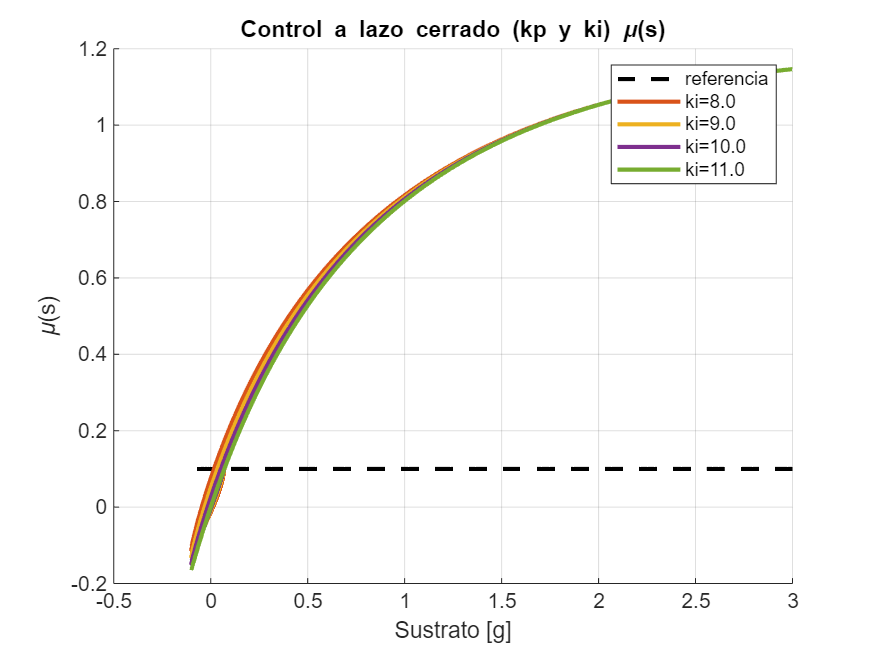

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = 0.1259;
modelParameters.mu_r=mu_r;
modelParameters.kp=0.05; % factor proporcional
% modelParameters.ki=0.1; % factor integrativa
e0=mu_r*1.5;

params={8, 9, 10, 11};
mus=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)
    modelParameters.ki=params{i};

    sim_out = sim('simulaciones/TP4_control_int', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrate = reshape(states(:,2), size(time)).*volume;
    Do = sim_out.Do.Data;
    mus{i} = sim_out.mu_s.Data;

    mu_r_vector = ones(1, length(mus{i}))*mu_r;
    
    error{i}=(mu_r_vector-mus{i});
    MSE{i} = immse(reshape(mu_r_vector, size(mus{i})), mus{i});

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Control a lazo cerrado (kp y ki) \mu(s)');
xlabel('Sustrato [g]');
ylabel('\mu(s)');
plot(sustrate, mu_r_vector, 'k--', 'LineWidth', 2);
plot(sustrate, mus{1}, 'LineWidth', 2);
plot(sustrate, mus{2}, 'LineWidth', 2);
plot(sustrate, mus{3}, 'LineWidth', 2);
plot(sustrate, mus{4}, 'LineWidth', 2);

legend('referencia' ...
    ,sprintf('ki=%.1f', params{1}), ...
    sprintf('ki=%.1f', params{2}), ...
    sprintf('ki=%.1f', params{3}), ...
    sprintf('ki=%.1f', params{4}));

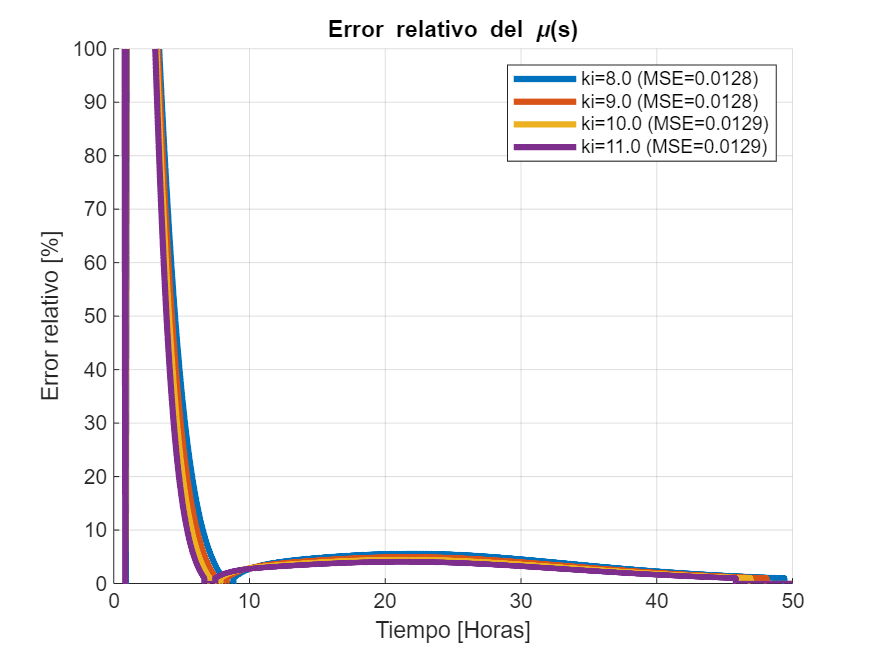


% Error relativo
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo del \mu(s)');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{2}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{3}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{4}), mu_r_vector), 'LineWidth', 3);

legend(sprintf('ki=%.1f (MSE=%.4f)', params{1}, MSE{1}), ...
    sprintf('ki=%.1f (MSE=%.4f)', params{2}, MSE{2}), ...
    sprintf('ki=%.1f (MSE=%.4f)', params{3}, MSE{3}), ...
    sprintf('ki=%.1f (MSE=%.4f)', params{4}, MSE{4}));

#### Conclusiones

Se puede ver que ahora con el término integrativo del error se elimina el error al estado estacionario, la convergencia a la referencia es eventual, y toma aproximadamente 50 horas, además este tiempo de convergencia es dependiente de la ganancia $k_i$ y $k_p$, pero estas también afectan la estabilidad y el sobrepico.

## Robustez del controlador a lazo cerrado (integrador)

Se comprueba la robustez al igual que antes, pero solo para el caso donde se tiene un integrador

### Variaciones en x0

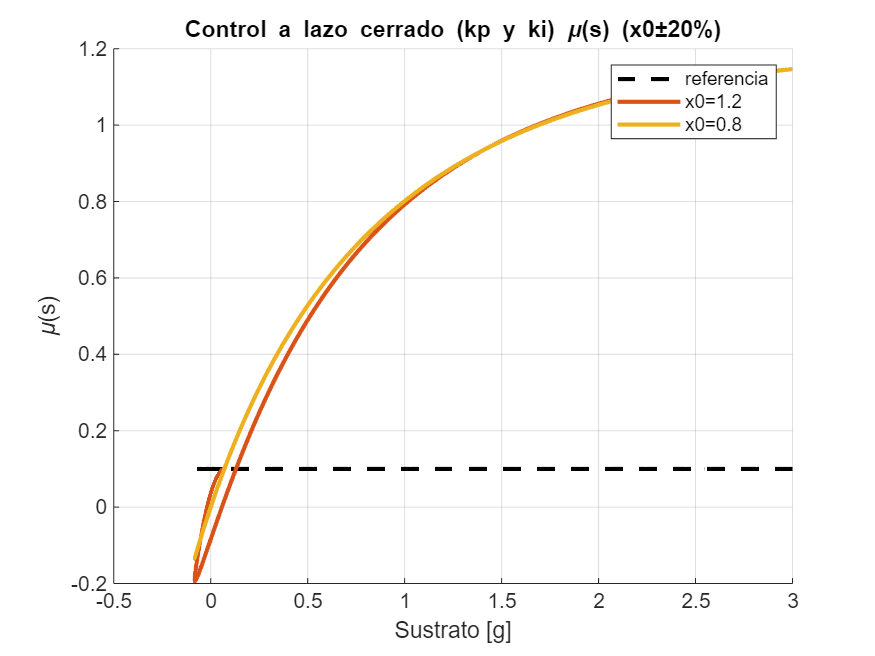

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = 0.1259;
modelParameters.mu_r=mu_r;
modelParameters.kp=0.05; % factor proporcional
modelParameters.ki=11; % factor integrativo
e0=mu_r*1.5;

params_x0={x0*(1.2),x0*(0.8)}; % más/menos 20% del x0
mus=cell(length(params_x0));
error=cell(length(params_x0));
MSE=cell(length(params_x0));
for i=1:length(params_x0)
    modelParameters.x0=params_x0{i};

    sim_out = sim('simulaciones/TP4_control_int', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrate = reshape(states(:,2), size(time)).*volume;
    Do = sim_out.Do.Data;
    mus{i} = sim_out.mu_s.Data;

    mu_r_vector = ones(1, length(mus{i}))*mu_r;
    
    error{i}=(mu_r_vector-mus{i});
    MSE{i} = immse(reshape(mu_r_vector, size(mus{i})), mus{i});

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Control a lazo cerrado (kp y ki) \mu(s) (x0±20%)');
xlabel('Sustrato [g]');
ylabel('\mu(s)');
plot(sustrate, mu_r_vector, 'k--', 'LineWidth', 2);
plot(sustrate, mus{1}, 'LineWidth', 2);
plot(sustrate, mus{2}, 'LineWidth', 2);

legend('referencia' ...
    ,sprintf('x0=%.1f', params_x0{1}), ...
    sprintf('x0=%.1f', params_x0{2}));

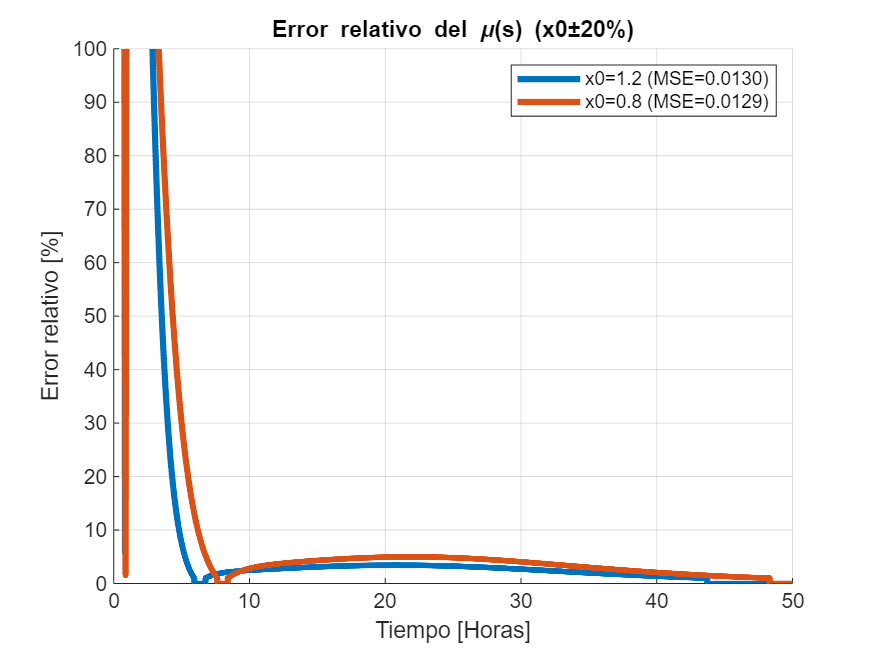


% Error relativo
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo del \mu(s) (x0±20%)');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{2}), mu_r_vector), 'LineWidth', 3);

legend(sprintf('x0=%.1f (MSE=%.4f)', params_x0{1}, MSE{1}), ...
    sprintf('x0=%.1f (MSE=%.4f)', params_x0{2}, MSE{2}));

#### Conclusiones

Se tienen variaciones en el transitorio, pero se tiene convergencia de todas formas en el mismo tiempo que antes, por lo que este controlador es muy robusto a variaciones de $x_0$

### Variaciones en ks1

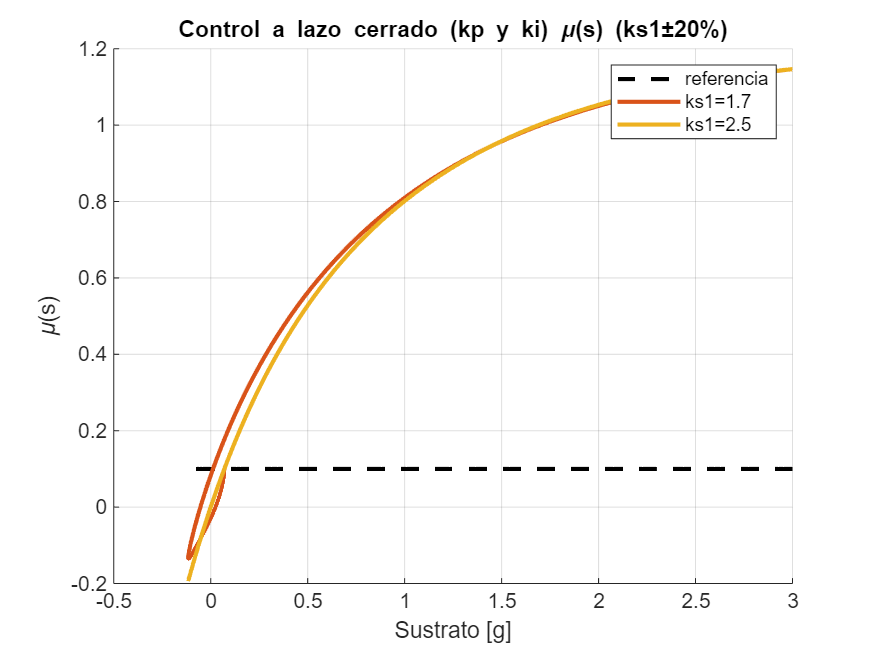

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = 0.1259;
modelParameters.mu_r=mu_r;
modelParameters.kp=0.05; % factor proporcional
modelParameters.ki=11; % factor integrativo
e0=mu_r*1.5;

params={ks1*(0.8), ks1*(1.2)};
mus=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)
    modelParameters.ks1=params{i};

    sim_out = sim('TP4_control_int', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrate = reshape(states(:,2), size(time)).*volume;
    Do = sim_out.Do.Data;
    mus{i} = sim_out.mu_s.Data;

    mu_r_vector = ones(1, length(mus{i}))*mu_r;
    
    error{i}=(mu_r_vector-mus{i});
    MSE{i} = immse(reshape(mu_r_vector, size(mus{i})), mus{i});

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Control a lazo cerrado (kp y ki) \mu(s) (ks1±20%)');
xlabel('Sustrato [g]');
ylabel('\mu(s)');
plot(sustrate, mu_r_vector, 'k--', 'LineWidth', 2);
plot(sustrate, mus{1}, 'LineWidth', 2);
plot(sustrate, mus{2}, 'LineWidth', 2);

legend('referencia' ...
    ,sprintf('ks1=%.1f', params{1}), ...
    sprintf('ks1=%.1f', params{2}));

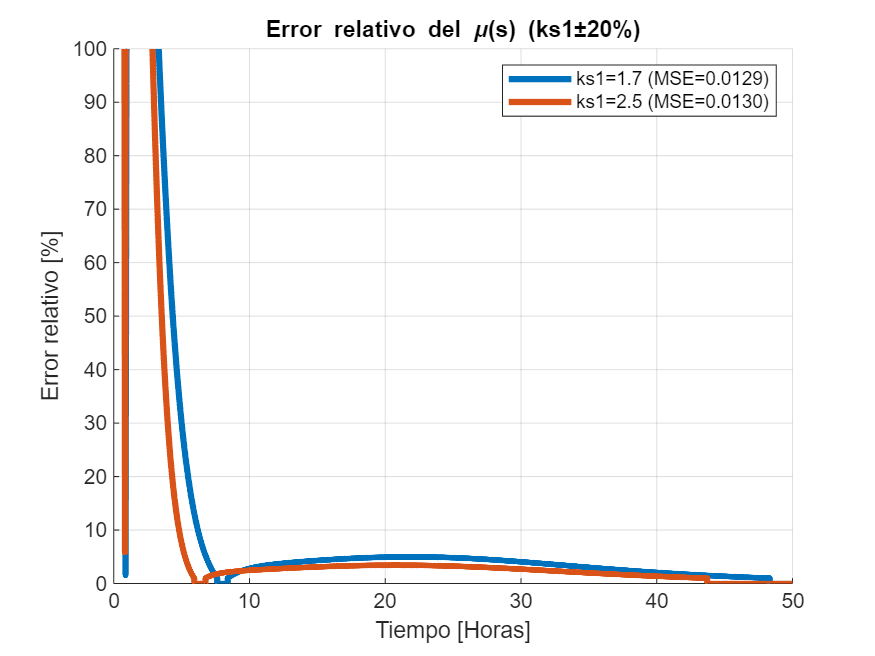


% Error relativo
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo del \mu(s) (ks1±20%)');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{2}), mu_r_vector), 'LineWidth', 3);

legend(sprintf('ks1=%.1f (MSE=%.4f)', params{1}, MSE{1}), ...
    sprintf('ks1=%.1f (MSE=%.4f)', params{2}, MSE{2}));

#### Conclusiones

Al igual que antes se tiene robustez ante variaciones de este parámetro, ya que se termina convergiendo al valor en el mismo tiempo que antes.

## Control linealizante

Se quiere regular la concentración de sustrato implementando un control linealizante

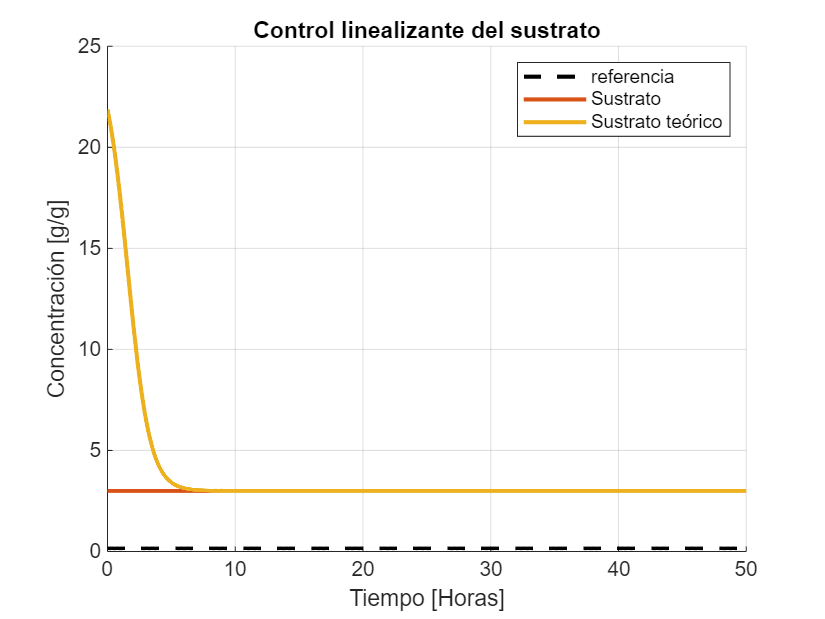

% referencia del sustrato (s*)
s_r=0.15; 

modelParameters.s_in=s_in;
modelParameters.s_r = s_r;
modelParameters.mu_r=mu_r;

params={1};
sustrates=cell(length(params));
biomass=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)

    sim_out = sim('simulaciones/TP4_control_linealizante', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass{i} = reshape(states(:,1), size(time));
    sustrates{i} = reshape(states(:,2), size(time));
    final_s= sim_out.final_s.Data;
    Do = sim_out.Do.Data;
    mu = sim_out.mu_s.Data;

    sustrate_vector_r = ones(length(sustrates{i}), 1)*s_r;
    
    error{i}=(sustrate_vector_r-sustrates{i});
    MSE{i} = immse(reshape(sustrate_vector_r, size(sustrates{i})), sustrates{i});

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Control linealizante del sustrato');
xlabel('Tiempo [Horas]');
ylabel('Concentración [g/g]');
plot(time, sustrate_vector_r, 'k--', 'LineWidth', 2);
plot(time, sustrates{1}, 'LineWidth', 2);
plot(time, final_s, 'LineWidth', 2);

legend('referencia', 'Sustrato', 'Sustrato teórico');

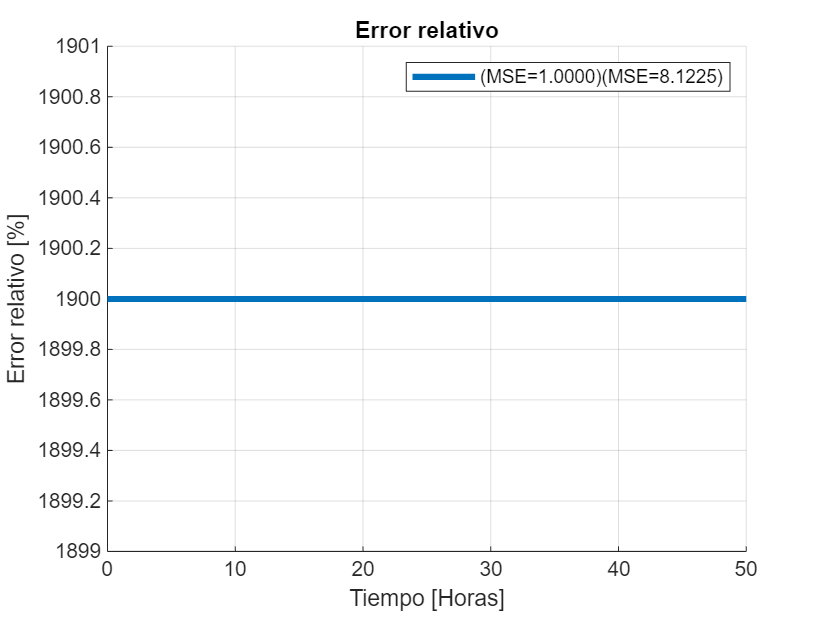


% Error relativo
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
% ylim([0 100])
plot(time, getRelativeError(abs(error{1}), sustrate_vector_r), 'LineWidth', 3);

legend(sprintf('(MSE=%.4f)', params{1}, MSE{1}));


% Plano de fase
% fig = figure();
% set(fig,'Position',[0 0 800 600]);
% hold on; grid on;
% title('Plano de fase');
% xlabel('Concentración [g/g]');
% ylabel('Concentración [g/g]');
% plot(sustrates{1}, biomass{1}, 'LineWidth', 2);

% legend('Estados 1');

#### Conclusiones

No entiendo exactamente la razón de la no convergencia, siendo además que se se llega al valor teórico de $s=s_{\textrm{in}} -x\;k_{\textrm{s1}}$

## Control linealizante con kp del error

Se agrega un término proporcional al error

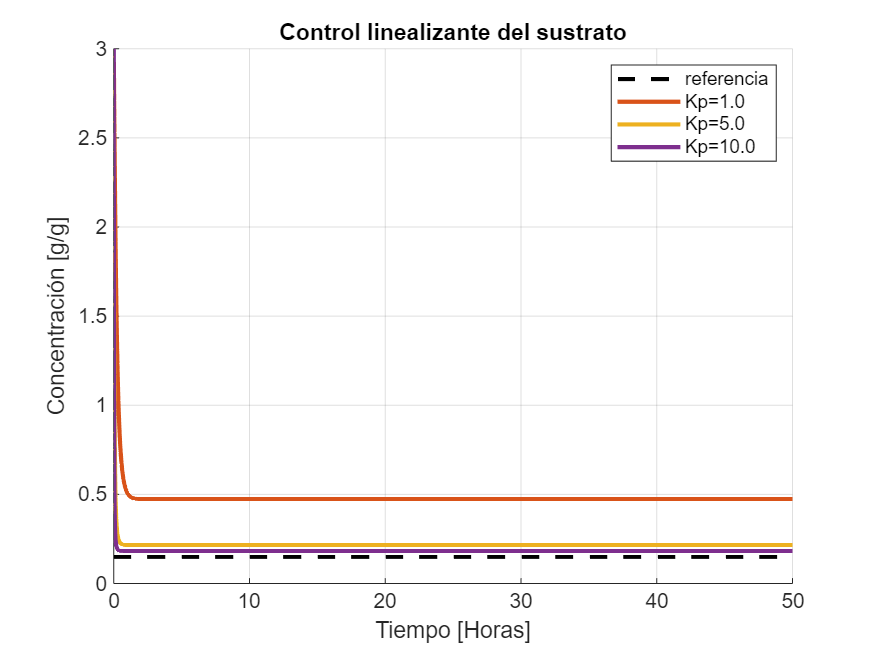

% referencia del sustrato (s*)
s_r=0.15; 

modelParameters.s_in=s_in;
modelParameters.s_r = s_r;
modelParameters.mu_r=mu_r;

params={1, 5, 10};
sustrates=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)
    modelParameters.kp=params{i};

    sim_out = sim('simulaciones/TP4_control_linealizante_kp', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrates{i} = reshape(states(:,2), size(time));
    Do = sim_out.Do.Data;
    mu = sim_out.mu_s.Data;

    sustrate_vector_r = ones(length(sustrates{i}), 1)*s_r;
    
    error{i}=(sustrate_vector_r-sustrates{i});
    MSE{i} = immse(reshape(sustrate_vector_r, size(sustrates{i})), sustrates{i});

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Control linealizante del sustrato');
xlabel('Tiempo [Horas]');
ylabel('Concentración [g/g]');
plot(time, sustrate_vector_r, 'k--', 'LineWidth', 2);
plot(time, sustrates{1}, 'LineWidth', 2);
plot(time, sustrates{2}, 'LineWidth', 2);
plot(time, sustrates{3}, 'LineWidth', 2);

legend('referencia', ...
    sprintf('Kp=%.1f', params{1}), ...
    sprintf('Kp=%.1f', params{2}), ...
    sprintf('Kp=%.1f', params{3}));

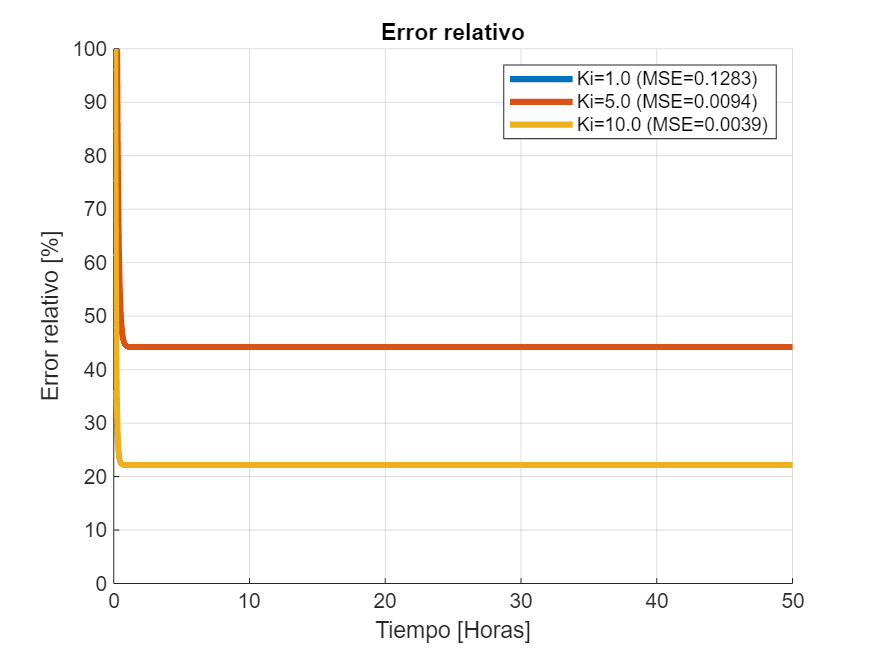


% Error relativo
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), sustrate_vector_r), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{2}), sustrate_vector_r), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{3}), sustrate_vector_r), 'LineWidth', 3);

legend(sprintf('Ki=%.1f (MSE=%.4f)', params{1}, MSE{1}), ...
    sprintf('Ki=%.1f (MSE=%.4f)', params{2}, MSE{2}),...
    sprintf('Ki=%.1f (MSE=%.4f)', params{3}, MSE{3}));

#### Conclusiones

Ahora se tiene algo que converge a un error menor, pero todavía se tiene un error al estado estacionario.

## Control linealizante con kp y ki del error

Se agrega un término proporcional al error

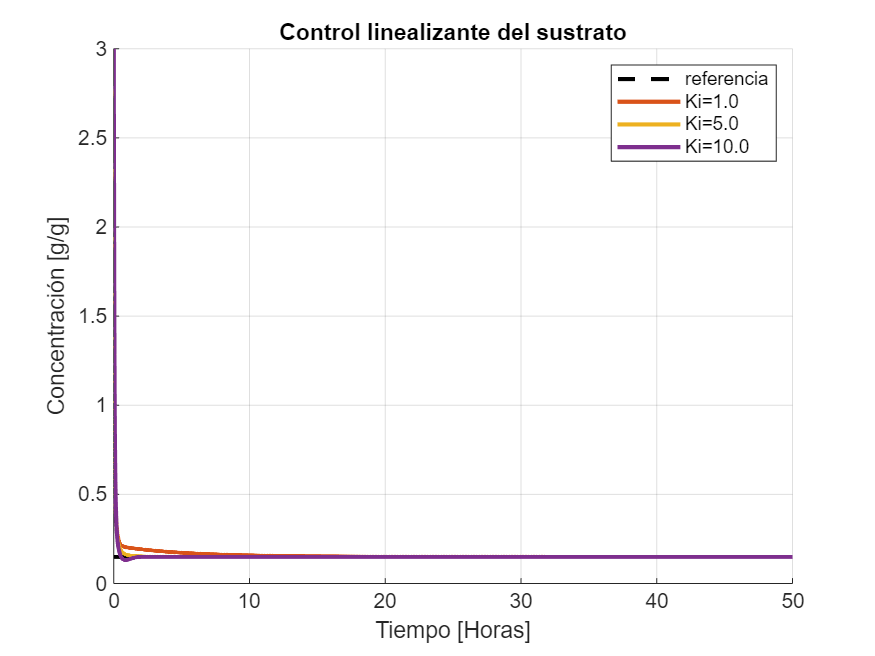

% referencia del sustrato (s*)
s_r=0.15; 

modelParameters.s_in=s_in;
modelParameters.s_r = s_r;
modelParameters.mu_r=mu_r;
modelParameters.kp=5;

params={1, 5, 10};
sustrates=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)
    modelParameters.ki=params{i};

    sim_out = sim('simulaciones/TP4_control_linealizante_ki', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrates{i} = reshape(states(:,2), size(time));
    Do = sim_out.Do.Data;
    mu = sim_out.mu_s.Data;

    sustrate_vector_r = ones(length(sustrates{i}), 1)*s_r;
    
    error{i}=(sustrate_vector_r-sustrates{i});
    MSE{i} = immse(reshape(sustrate_vector_r, size(sustrates{i})), sustrates{i});

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Control linealizante del sustrato');
xlabel('Tiempo [Horas]');
ylabel('Concentración [g/g]');
plot(time, sustrate_vector_r, 'k--', 'LineWidth', 2);
plot(time, sustrates{1}, 'LineWidth', 2);
plot(time, sustrates{2}, 'LineWidth', 2);
plot(time, sustrates{3}, 'LineWidth', 2);

legend('referencia', ...
    sprintf('Ki=%.1f', params{1}), ...
    sprintf('Ki=%.1f', params{2}), ...
    sprintf('Ki=%.1f', params{3}));

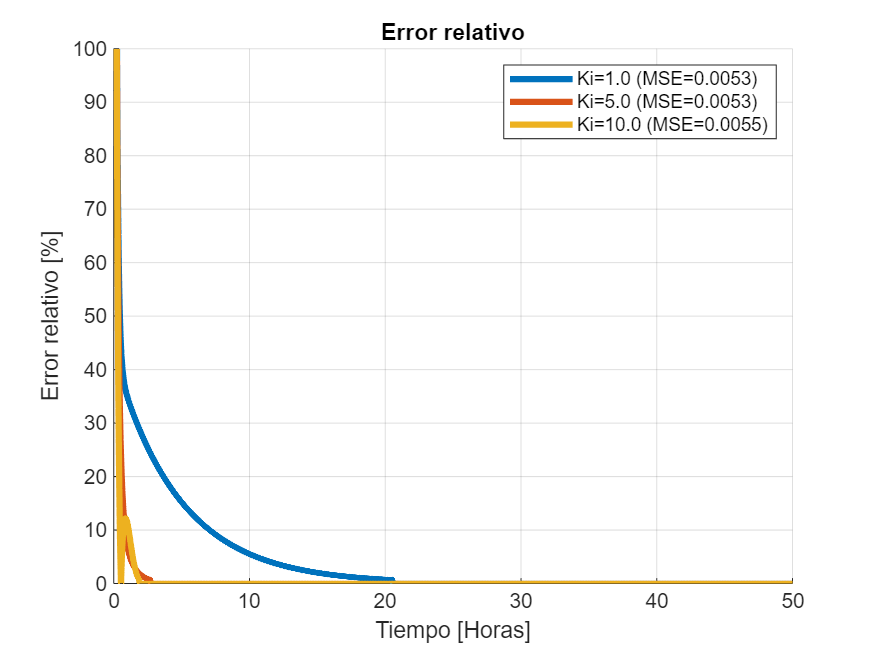


% Error relativo
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), sustrate_vector_r), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{2}), sustrate_vector_r), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{3}), sustrate_vector_r), 'LineWidth', 3);

legend(sprintf('Ki=%.1f (MSE=%.4f)', params{1}, MSE{1}), ...
    sprintf('Ki=%.1f (MSE=%.4f)', params{2}, MSE{2}),...
    sprintf('Ki=%.1f (MSE=%.4f)', params{3}, MSE{3}));

#### Conclusiones

Converge con error nulo, es el mejor caso posible. Además con una buena gannacia de integración $k_i$ se tiene una convergencia en menos de 5 horas, que es bastante bueno.

## Control linealizante (sin kp ni ki) con variaciones en los parámetros

Que pasa si se tienen variaciones del 20% en los parámetros del controlador  (ks1) para el caso sin proporción ni integración del error.

### Variaciones en ks1

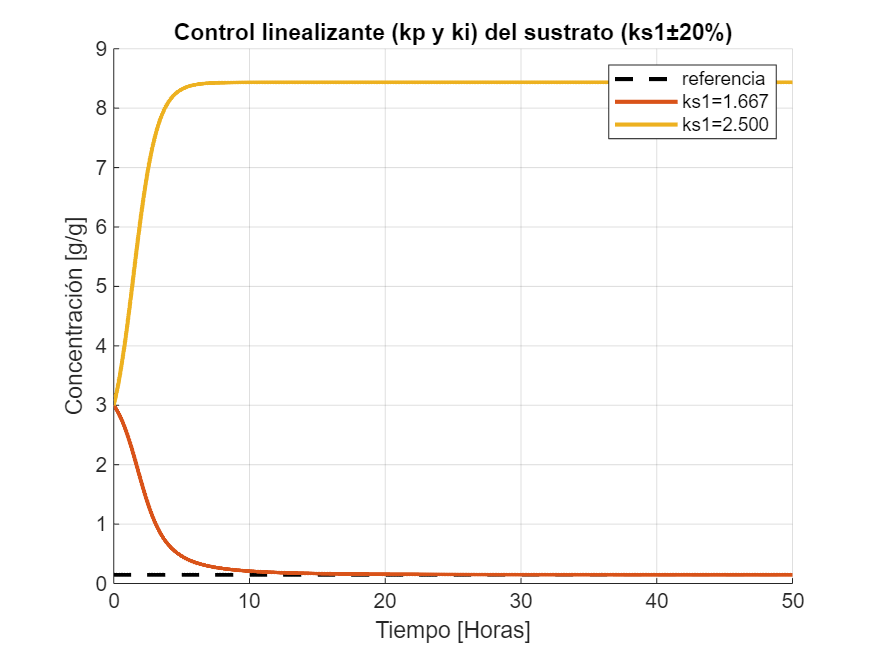

% referencia del sustrato (s*)
s_r=0.15; 

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = s_r;
modelParameters.mu_r=mu_r;

params={ks1*(0.8), ks1*(1.2)};
sustrates=cell(length(params));
biomass=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)
    modelParameters.ks1 = params{i};

    sim_out = sim('simulaciones/TP4_control_linealizante', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass{i} = reshape(states(:,1), size(time));
    sustrates{i} = reshape(states(:,2), size(time));
    Do = sim_out.Do.Data;
    mu = sim_out.mu_s.Data;

    sustrate_vector_r = ones(length(sustrates{i}), 1)*s_r;
    
    error{i}=(sustrate_vector_r-sustrates{i});
    MSE{i} = immse(reshape(sustrate_vector_r, size(sustrates{i})), sustrates{i});

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Control linealizante (kp y ki) del sustrato (ks1±20%)');
xlabel('Tiempo [Horas]');
ylabel('Concentración [g/g]');
plot(time, sustrate_vector_r, 'k--', 'LineWidth', 2);
plot(time, sustrates{1}, 'LineWidth', 2);
plot(time, sustrates{2}, 'LineWidth', 2);

legend('referencia', ...
    sprintf('ks1=%.3f', params{1}), ...
    sprintf('ks1=%.3f', params{2}));

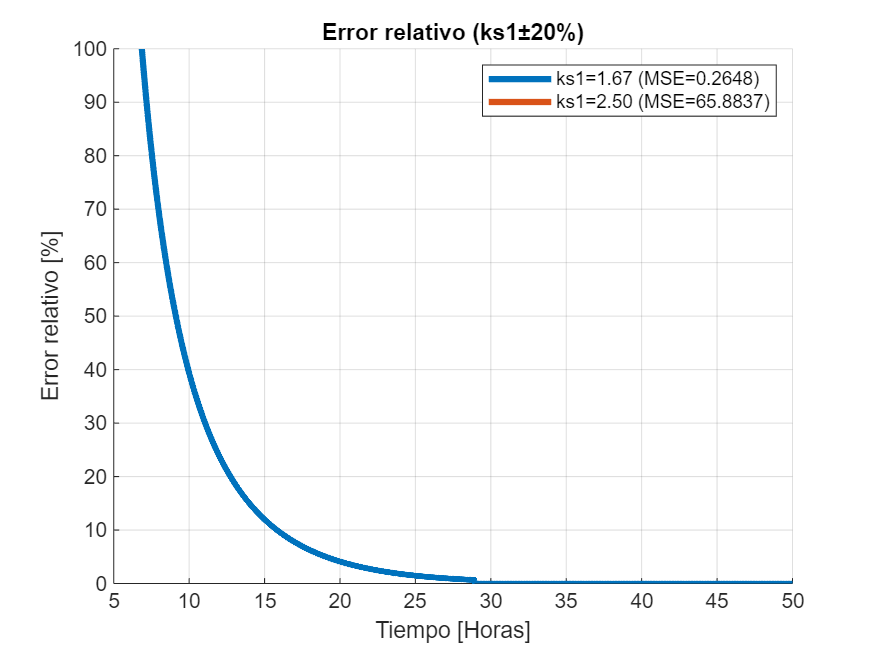


% Error relativo
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo (ks1±20%)');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), sustrate_vector_r), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{2}), sustrate_vector_r), 'LineWidth', 3);

legend(sprintf('ks1=%.2f (MSE=%.4f)', params{1}, MSE{1}), ...
    sprintf('ks1=%.2f (MSE=%.4f)', params{2}, MSE{2}));

#### Conclusiones

Es muy dependiente de ks1. Varía demasiado. Si se tiene un ks1-20% el error converge a cero eventualmente (en 30hs), pero si se tiene un ks1+20%, el error diverge y no sirve el control. Por lo que no es para nada robusto ante variaciones de este parámetro.

### Control linealizante (kp y ki) con variaciones en los parámetros

Que pasa si se tienen variaciones del 20% en los parámetros del controlador

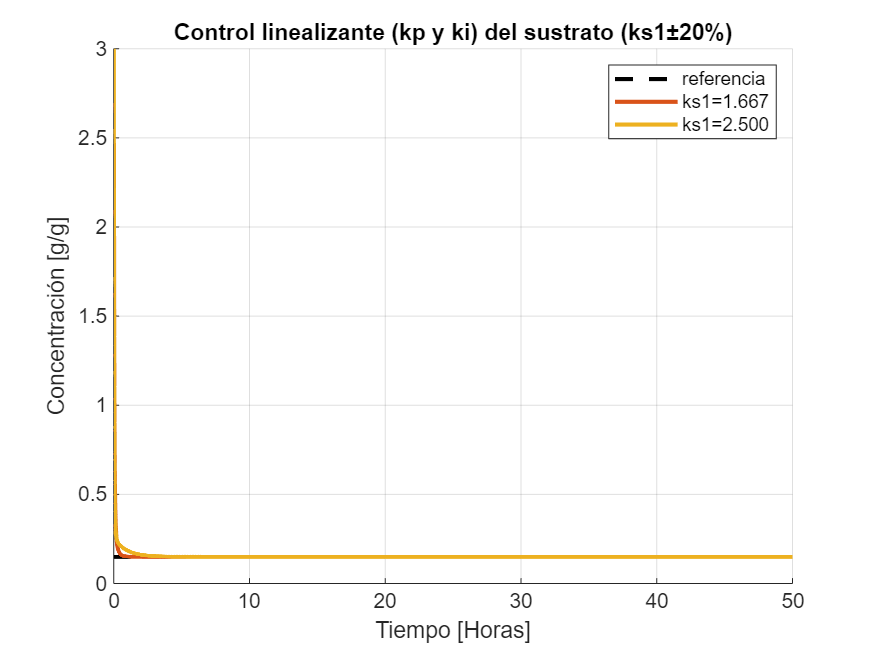

% referencia del sustrato (s*)
s_r=0.15; 

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = s_r;
modelParameters.mu_r=mu_r;
modelParameters.kp=10; % factor proporcional
modelParameters.ki=10;

params={ks1*(0.8), ks1*(1.2)};
sustrates=cell(length(params));
biomass=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)
    modelParameters.ks1 = params{i};

    sim_out = sim('simulaciones/TP4_control_linealizante_ki', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass{i} = reshape(states(:,1), size(time));
    sustrates{i} = reshape(states(:,2), size(time));
    Do = sim_out.Do.Data;
    mu = sim_out.mu_s.Data;

    sustrate_vector_r = ones(length(sustrates{i}), 1)*s_r;
    
    error{i}=(sustrate_vector_r-sustrates{i});
    MSE{i} = immse(reshape(sustrate_vector_r, size(sustrates{i})), sustrates{i});

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Control linealizante (kp y ki) del sustrato (ks1±20%)');
xlabel('Tiempo [Horas]');
ylabel('Concentración [g/g]');
plot(time, sustrate_vector_r, 'k--', 'LineWidth', 2);
plot(time, sustrates{1}, 'LineWidth', 2);
plot(time, sustrates{2}, 'LineWidth', 2);

legend('referencia', ...
    sprintf('ks1=%.3f', params{1}), ...
    sprintf('ks1=%.3f', params{2}));

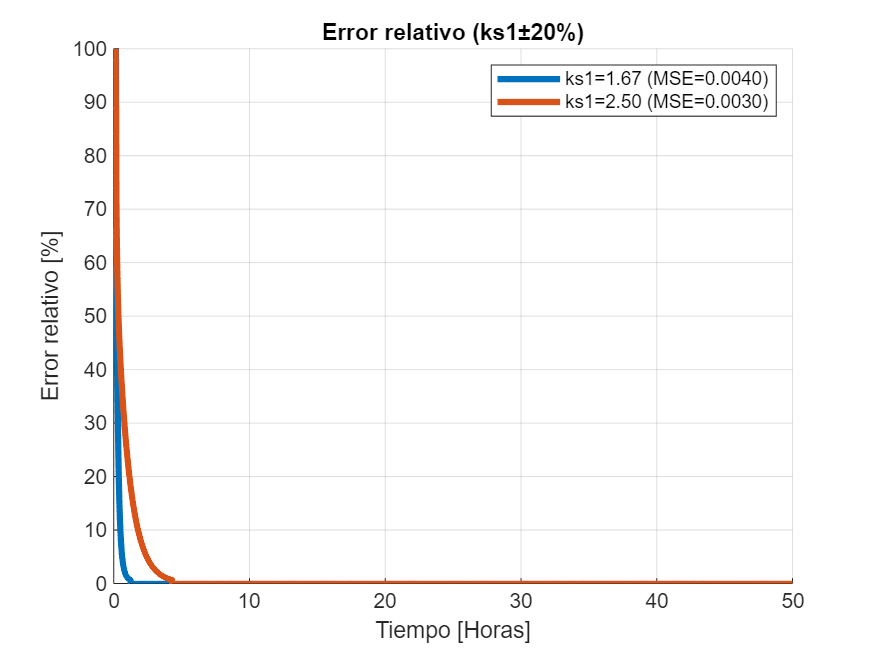


% Error relativo
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo (ks1±20%)');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), sustrate_vector_r), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{2}), sustrate_vector_r), 'LineWidth', 3);

legend(sprintf('ks1=%.2f (MSE=%.4f)', params{1}, MSE{1}), ...
    sprintf('ks1=%.2f (MSE=%.4f)', params{2}, MSE{2}));

#### Conclusiones

Ahora el error converge a cero y se tiene un sistema robusto contra variaciones del ks1, el peor caso en cuando se tiene un 20% más en $k_{\textrm{s1}}$, ya que el sistema converge a error cero para 5 horas, en cambio con 20% menos de error converge a cero en menos de 2 horas.

## Caso: no se sabe el consumo de sustrato

El consumo de sustrato es $\mu \left(s\right)$, y se asume desconocido. Por lo que simplemente lo ignoro del controlador

### Solo con término proporcional al error

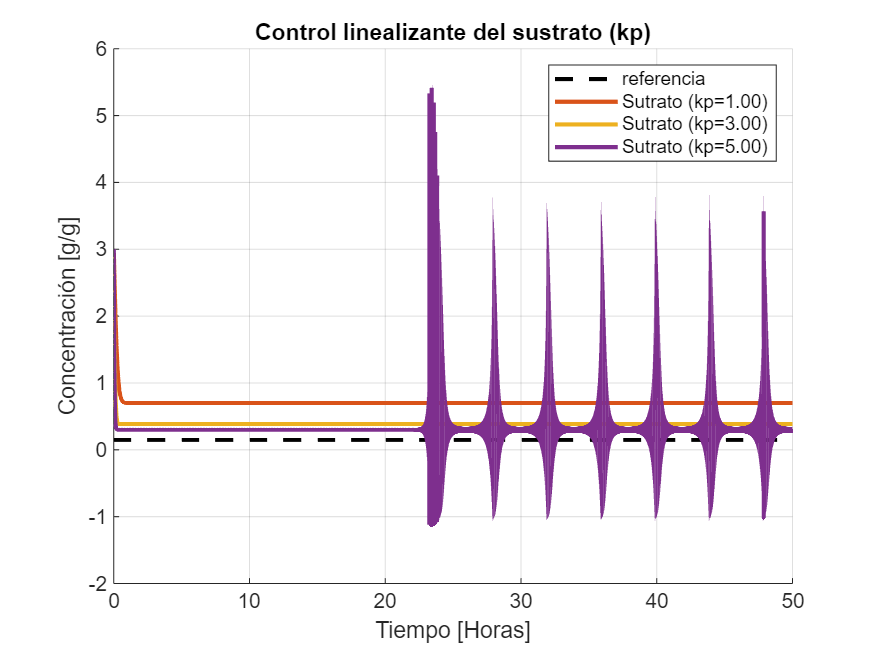

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = s_r;
modelParameters.mu_r=mu_r;

params={1, 3, 5};
sustrates=cell(length(params));
biomass=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)
    modelParameters.kp = params{i};

    sim_out = sim('simulaciones/TP4_control_linealizante_sin_mu', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass{i} = reshape(states(:,1), size(time));
    sustrates{i} = reshape(states(:,2), size(time));
    Do = sim_out.Do.Data;
    mu = sim_out.mu_s.Data;

    sustrate_vector_r = ones(length(sustrates{i}), 1)*s_r;
    
    error{i}=(sustrate_vector_r-sustrates{i});
    MSE{i} = immse(reshape(sustrate_vector_r, size(sustrates{i})), sustrates{i});

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Control linealizante del sustrato (kp)');
xlabel('Tiempo [Horas]');
ylabel('Concentración [g/g]');
plot(time, sustrate_vector_r, 'k--', 'LineWidth', 2);
plot(time, sustrates{1}, 'LineWidth', 2);
plot(time, sustrates{2}, 'LineWidth', 2);
plot(time, sustrates{3}, 'LineWidth', 2);

legend('referencia', ...
    sprintf('Sutrato (kp=%.2f)', params{1}), ...
    sprintf('Sutrato (kp=%.2f)', params{2}), ...
    sprintf('Sutrato (kp=%.2f)', params{3}));

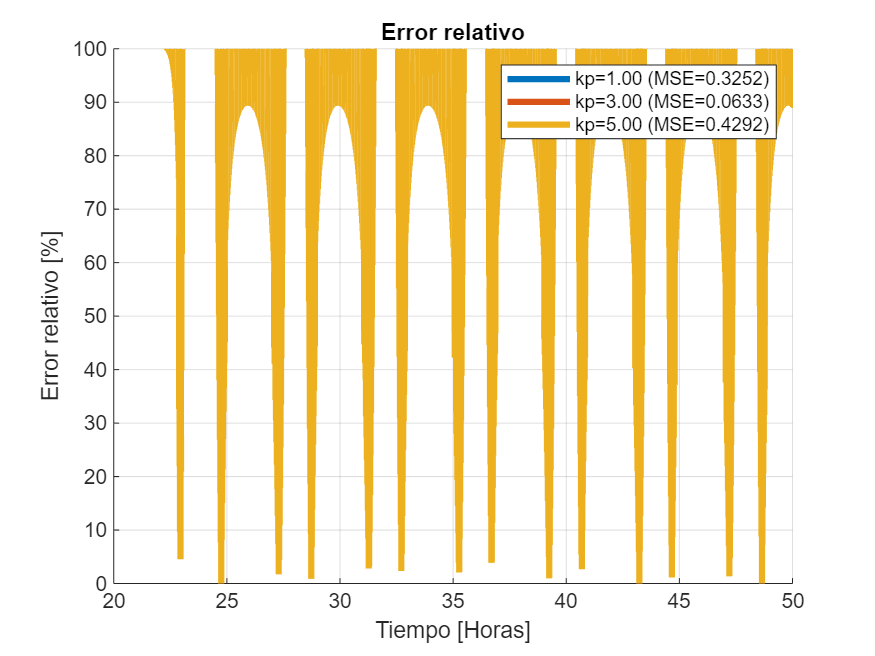


% Error relativo
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), sustrate_vector_r), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{2}), sustrate_vector_r), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{3}), sustrate_vector_r), 'LineWidth', 3);

legend(sprintf('kp=%.2f (MSE=%.4f)', params{1}, MSE{1}), ...
    sprintf('kp=%.2f (MSE=%.4f)', params{2}, MSE{2}),...
    sprintf('kp=%.2f (MSE=%.4f)', params{3}, MSE{3}));

#### Conclusiones

Converge a un error de estado estacionario que es menor cuanto más grande sea el $k_p$, pero si se elige un $k_p$ muy grande (mayor a 5 para este caso), el error diverge y se hace inestable el sistema. Por lo que agregando un término integrativo debería eliminar este error al estado estacionario, además lo podría hacer más estable al sistema.

### Con término integrativo al error

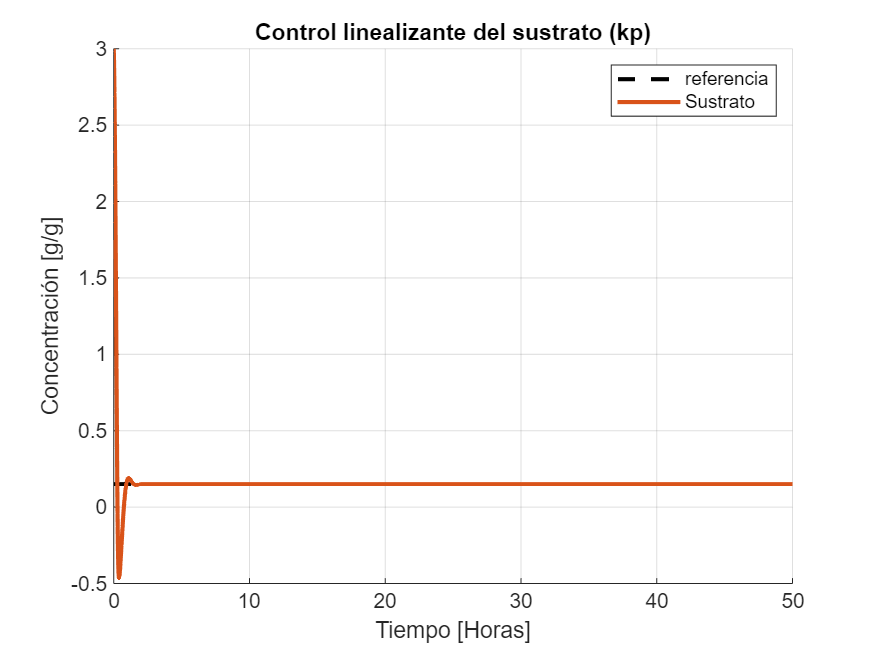

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = s_r;
modelParameters.mu_r=mu_r;
modelParameters.kp=1;
modelParameters.ki=10;

params={0};
sustrates=cell(length(params));
biomass=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)
    modelParameters.ks = params{i};

    sim_out = sim('simulaciones/TP4_control_linealizante_sin_mu_ki', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass{i} = reshape(states(:,1), size(time));
    sustrates{i} = reshape(states(:,2), size(time));
    Do = sim_out.Do.Data;
    mu = sim_out.mu_s.Data;

    sustrate_vector_r = ones(length(sustrates{i}), 1)*s_r;
    
    error{i}=(sustrate_vector_r-sustrates{i});
    MSE{i} = immse(reshape(sustrate_vector_r, size(sustrates{i})), sustrates{i});

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Control linealizante del sustrato (kp)');
xlabel('Tiempo [Horas]');
ylabel('Concentración [g/g]');
plot(time, sustrate_vector_r, 'k--', 'LineWidth', 2);
plot(time, sustrates{1}, 'LineWidth', 2);

legend('referencia', 'Sustrato');

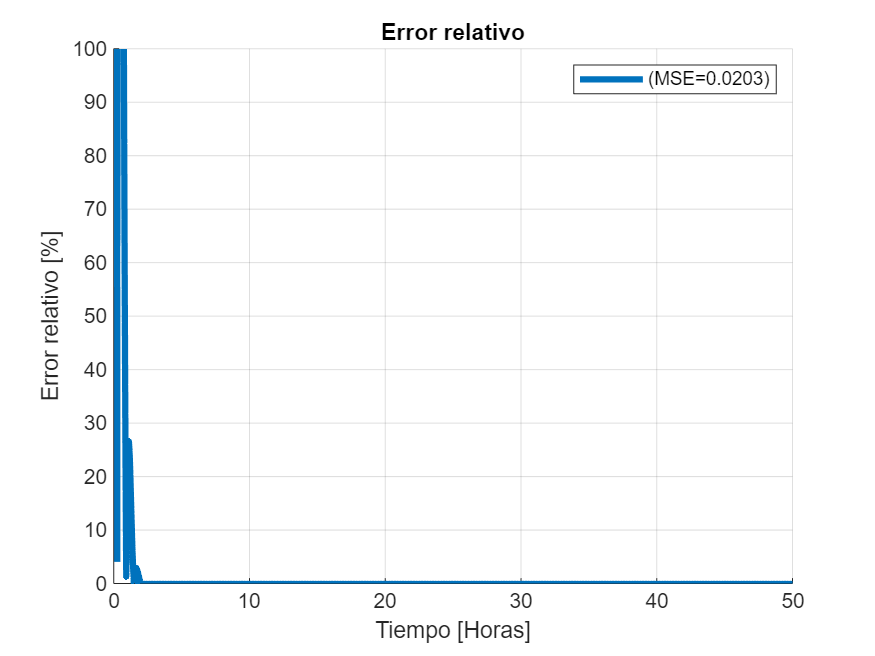


% Error relativo
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), sustrate_vector_r), 'LineWidth', 3);

legend(sprintf('(MSE=%.4f)', MSE{1}));

#### Conclusiones

Como se puede observar el sistema se volvió muy estable y además converge con error al estado estacionario nulo, inclusive la convergencia se da en un tiempo muy bueno (menor a las 5 horas).

### Robustez del controlador anterior

Ahora se verifica que tan bueno es este controlador, introduciendo perturbaciones en D del 20%. De esta manera podremos corroborar si el tomar $\mu \left(s\right)=1$es realmente una solución

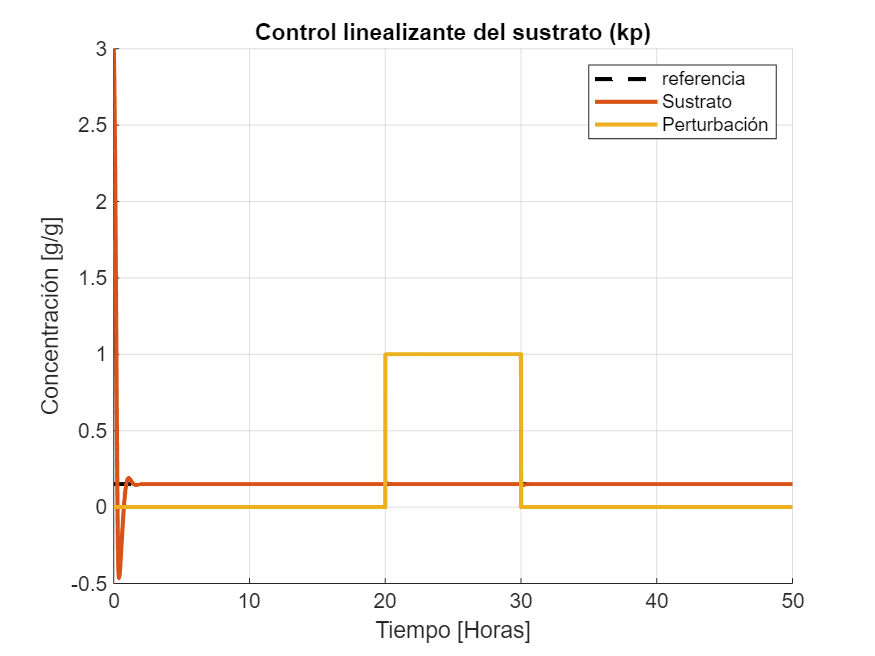

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = s_r;
modelParameters.mu_r=mu_r;
modelParameters.kp=1;
modelParameters.ki=10;

% Parámetros de la perturbación
disturbanceParameters.start = 20;
disturbanceParameters.end = 30;
disturbanceParameters.percentage = 0.2;

params={0};
sustrates=cell(length(params));
biomass=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)
    modelParameters.ks = params{i};

    sim_out = sim('simulaciones/TP4_control_linealizante_perturbanciones', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass{i} = reshape(states(:,1), size(time));
    sustrates{i} = reshape(states(:,2), size(time));
    Do = sim_out.Do.Data;
    mu = sim_out.mu_s.Data;
    disturbance = sim_out.disturbance.Data;

    sustrate_vector_r = ones(length(sustrates{i}), 1)*s_r;
    
    error{i}=(sustrate_vector_r-sustrates{i});
    MSE{i} = immse(reshape(sustrate_vector_r, size(sustrates{i})), sustrates{i});

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Control linealizante del sustrato (kp)');
xlabel('Tiempo [Horas]');
ylabel('Concentración [g/g]');
plot(time, sustrate_vector_r, 'k--', 'LineWidth', 2);
plot(time, sustrates{1}, 'LineWidth', 2);
plot(time, disturbance/0.2, 'LineWidth', 2);

legend('referencia', 'Sustrato', 'Perturbación');

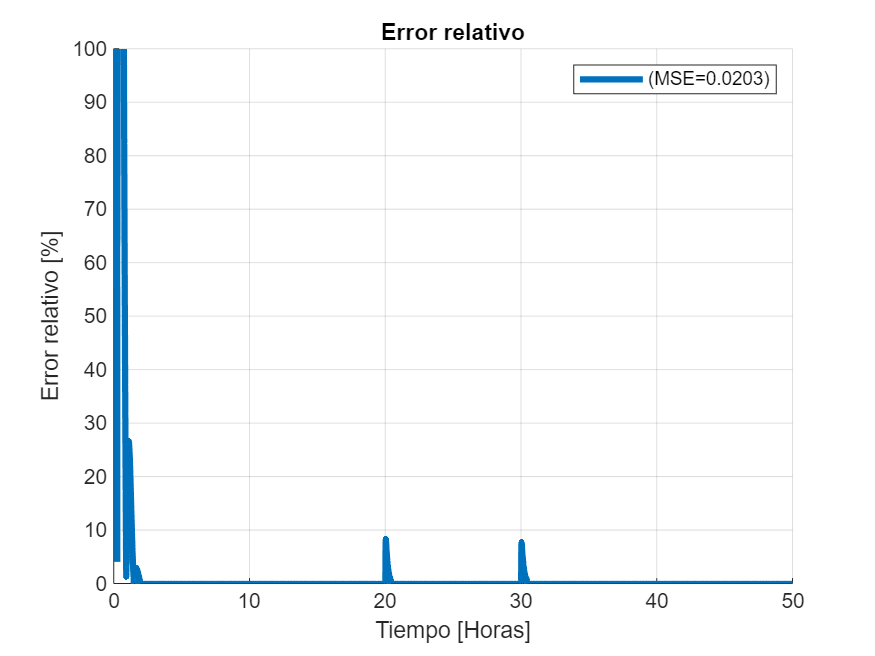


% Error relativo
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), sustrate_vector_r), 'LineWidth', 3);

legend(sprintf('(MSE=%.4f)', MSE{1}));

#### Conclusiones

Como se puede observar, la perturbación afecta la salida, pero no de una manera muy significativa, por lo que este controlador es muy robusto y con rechazo a perturbaciones muy buenas.